# Exercise 1 - series 1

# **Analyse participation élections cantonales 2017**

The objective of the exercise is mainly to manipulate data contained in tables, the analysis will therefore remain brief.

The correction is very approximative, but it is mainly a question to see how to use the different routines.

## Load data from Excel to a Matlab table

- The routine *readtable()* is used to load data from a file. The routine allows different file types (.txt, .dat, .xlsx,...)

- It is also possible to use the Import Data utility found in the *Home* menu.

- Some columns have been identified directly by the routine as catagorical

opts = spreadsheetImportOptions("NumVariables", 26);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "A2:Z197";

% Specify column names and types
opts.VariableNames = ["Country", "Code", "Region", "Income", "Level", "x2000", "x2001", "x2002", "x2003", "x2004", "x2005", "x2006", "x2007", "x2008", "x2009", "x2010", "x2011", "x2012", "x2013", "x2014", "x2015", "x2016", "x2017", "x2018", "pop2000", "pop2018"];
opts.VariableTypes = ["string", "categorical", "string", "categorical", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Country", "Region"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Country", "Code", "Region", "Income", "Level"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("/home/giboul/Desktop/DoE/D1/Series_DOE_1_data_scientifc_publication.xlsx", opts, "UseExcel", false);
% Clear temporary variables
clear opts


The columns region is defined as categorical

data.Region=categorical(data.Region);

## Summary of the data

The summary routine produces some statistical data from a table. In this ase we have chosen a few columns to illustrate the use of this function.

summary(data(:,[3,4,6,24:end]))


196×6 table

Variables:

    Region: categorical (7 categories)
    Income: categorical (4 categories)
    x2000: double
    x2018: double
    pop2000: double
    pop2018: double

Statistics for applicable variables:

               NumMissing       Min           Median             Max               Mean              Std      

    Region         0                                                                                          
    Income         0                                                                                          
    x2000          0               0           76.3550        3.0478e+05        5.3607e+03        2.4786e+04  
    x2018          0               0          356.6200        5.

## `2. Adding data to a table`

The statement asked to connect population data. In fact they are already in the right sheet of Excel.

But ta table can be merge to another table if they have the same number of row, as the eyample below:

% create a table of one columns and 5 rows
tbl_A=table(categorical({'A';'B';'C';'A';'B'}))

tbl_A = 5×1 table
    Var1
    ____

     A  
     B  
     C  
     A  
     B  


% create an array of 2 columns and 5 rows
B=randn(5,2)

B =     0.5377   -1.3077
    1.8339   -0.4336
   -2.2588    0.3426
    0.8622    3.5784
    0.3188    2.7694


% transform the array in table
tbl_B=array2table(B)

tbl_B = 5×2 table
      B1          B2   
    _______    ________

    0.53767     -1.3077
     1.8339    -0.43359
    -2.2588     0.34262
    0.86217      3.5784
    0.31877      2.7694


% concatenate the two tables
tbl_A=[tbl_A tbl_B]

tbl_A = 5×3 table
    Var1      B1          B2   
    ____    _______    ________

     A      0.53767     -1.3077
     B       1.8339    -0.43359
     C      -2.2588     0.34262
     A      0.86217      3.5784
     B      0.31877      2.7694


% compute a new columns based on a calculation
tbl_A.CC=cumsum(tbl_A.B1)

tbl_A = 5×4 table
    Var1      B1          B2         CC   
    ____    _______    ________    _______

     A      0.53767     -1.3077    0.53767
     B       1.8339    -0.43359     2.3716
     C      -2.2588     0.34262    0.11271
     A      0.86217      3.5784    0.97488
     B      0.31877      2.7694     1.2936


## `3. Check for possible aberrations in the data`

Look for aberrations in the data using different types of graphics.

The first try could be a plot() or a semilogy() depending on the dynamic of the data.

In the graph here below the 19 series of scientific publications is plotted. the huge pic just after the start needs to be investigated further. There is also a few other pics to analyse.

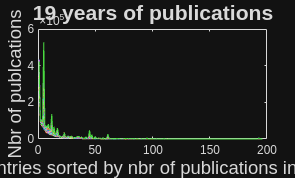

plot(sortrows(data{:,6:24},"descend"))
title('19 years of publications',"FontSize",16)
xlabel('Countries sorted by nbr of publications in 2000',"FontSize",14)
ylabel('Nbr of publcations',"FontSize",14)

In the graph below, the same data has been plotted in a log scale. In this case, it is the end of the series that shows huge changes which are explaned by the fact that a few countries have so few scientific activities that the change from one year to another can be important when observed with a log scale. Globaly  changes of one and even two order of magnitude can be observed but with a yearly progression that makes those data possible. It is possible to use the magnifier to look within the pics.

This type of graphics are sometimes called cobweb. They are practical to check a lot of time series paralllely.

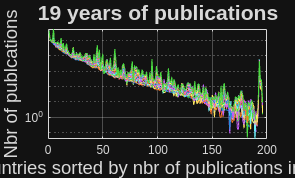

semilogy(sortrows(data{:,6:24},"descend"))
title('19 years of publications',"FontSize",16)
xlabel('Countries sorted by nbr of publications in 2000',"FontSize",14)
ylabel('Nbr of publcations',"FontSize",14)
grid on

An other way to look at the data is by looking at it by year. This is done by transposing the matrix of data. Nothing jump out of the graph, even if it is possible to observe that in a lot of countrie the nbr of publications evolves parallely. A few other have different dynamics

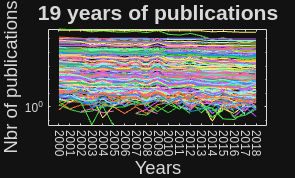

semilogy(sortrows(data{:,6:24}',"descend"))
title('19 years of publications',"FontSize",16)
xlabel('Years',"FontSize",14)
xticks(1:19)
xticklabels(2000:2018)
set(gca,"XTickLabelRotation",-90)

ylabel('Nbr of publications',"FontSize",14)

At that level it is interesting to look at the data with some categories. This data base has two categories: regions and economic levels. For this type of observation, the conditional access to the elements of a matrix or a table is an interesting feature. 

Here below the data for only East Asia & Pacific is plotted. The scrutiny of the data is easier tha previously. At the botom we can observe that some data is missing or zero for some countries with very low level of publication.

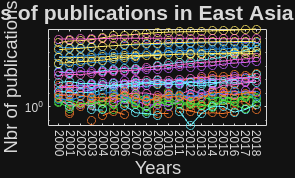

semilogy(table2array(data(data.Region=='East Asia & Pacific',6:24))','-o')
title('19 years of publications in East Asia & Pacific',"FontSize",16)
xlabel('Years',"FontSize",14)
xticks(1:19)
xticklabels(2000:2018)
set(gca,"XTickLabelRotation",-90)
ylabel('Nbr of publications',"FontSize",14)

Identicaly for the graphic below whoc h present the evolution of the nbr of publications for the counstries of South amarica

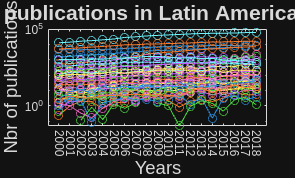


semilogy(table2array(data(data.Region=='Latin America & Caribbean',6:24))','-o')
title('19 years of publications in Latin America & Caribbean',"FontSize",16)
xlabel('Years',"FontSize",14)
xticks(1:19)
xticklabels(2000:2018)
set(gca,"XTickLabelRotation",-90)
ylabel('Nbr of publications',"FontSize",14)

When there is less data, the analysis of the plots is evidently easier.

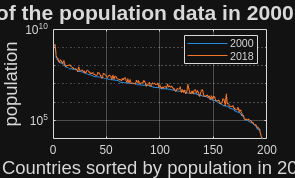

semilogy(sortrows(data{:,25:26},"descend"))
title('check of the population data in 2000 and 2018',"FontSize",16)
xlabel('Countries sorted by population in 2000',"FontSize",14)
ylabel('population',"FontSize",14)
grid on
legend('2000','2018')

Some population increases seem huge. Let's check the relative change $R_P=\frac{P_{2018}-P_{2000}}{P_{2000}}$

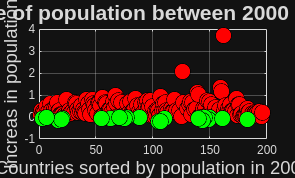

[A,index_sort]=sortrows(data{:,25:26},"descend");
B=(A(:,2)-A(:,1))./A(:,1);
Index_up=1:196;
plot(Index_up(B>0),B(B>0),'ok','MarkerFaceColor','r','MarkerSize',12)

title('Increase of population between 2000 and 2018',"FontSize",16)
xlabel('Countries sorted by population in 2000',"FontSize",14)
ylabel('Increas in population',"FontSize",14)
grid

hold on
plot(index_sort(B<=0),B(B<=0),'ok','MarkerFaceColor','g','MarkerSize',12)
hold off

Some countries (in green) have a decrease in population. The minimum is -20% for 

[rp_min,index_min]=min(B);
a=data{index_sort(index_min),1};
pop_a=data{index_sort(index_min),26}

pop_a = 2801543

disp(a)

Lithuania


Some countries (in red) have a huge increase in their population. The maximun is 370% for

[rp_max,index_max]=max(B);
b=data{index_sort(index_max),1};
pop_b=data{index_sort(index_max),26}

pop_b = 2781682

disp(b)

Qatar


Both countries have a relatively small population arround 3 milions inhabitants. The real big increase have to be found at the left hand side of the graphic, for example 

A small tool to see the country coresponding to a point in the graphic.

x=111

x = 111

B(x)

ans = 0.6687

c=data{index_sort(x),1}

c = "Sierra Leone"

pop_c=data{index_sort(x),26}

pop_c = 7650149

## 4. Definition of categories

In fact the categories have been defined in the first step when loading the data. 

The columns *region* is defined as categorical just after the nload of the data.

## 5. Agregation of data by categories

A new table called *data_Asia* is made with the data agragated by level of income. It is the varfun() function that let us deal with the slection of  some data by their category:

- The routine *varfun() *expects a function whose parameters are provided afterwards. It can be a standard Matlab function like here *sum() *but it can also be a function developed by the user.

- The expression data(data.Region=='East Asia & Pacific',:) provides the function with the part of the data table that contains the data for East Asia & Pacific.

- The use of the 'InputVariable' keyword makes it possible to announce the variables on which the function will be applied, these are introduced with braces if there are several.

- The use of the keyword 'groupingVariable' makes it possible to announce the discriminating variables, these are introduced with braces if there are several of them, which is not the case here.

data_Asia=varfun(@sum,data(data.Region=='East Asia & Pacific',:),'InputVariable',{'x2000','x2018','pop2000','pop2018'},...
    'groupingVariable','Income');

### Computing of the rate of publication per million of inhabitants

Two new columns with the ratio of publication for 2000 and 2018 are added to the table data_Asia. This illustrate how to perform calculations on columns

data_Asia.R2000=data_Asia.sum_x2000 ./ data_Asia.sum_pop2000*1e6;
data_Asia.R2018=data_Asia.sum_x2018 ./ data_Asia.sum_pop2018*1e6;
disp(data_Asia)

          Income           GroupCount    sum_x2000     sum_x2018     sum_pop2000    sum_pop2018     R2000     R2018 
    ___________________    __________    __________    __________    ___________    ___________    _______    ______

    High income                 8        1.4534e+05    2.3843e+05    2.0125e+08     2.1412e+08       722.2    1113.5
    Low income                  1              3.61         87.42    2.2929e+07      2.555e+07     0.15744    3.4216
    Lower middle income        14            1083.7         34189    4.4371e+08      5.613e+08      2.4424    60.911
    Upper middle income         7             56082    5.6459e+05    1.3498e+09     1.4947e+09      41.549    377.71



## 6. Bubble plot size of the population vs the number of publications by regions

### Statistics per category

The routine *grpstat* produce a table with required statistics. The use of the key word *DataVars* anounce the variable to be analysed.

stats_pop=grpstats(data,'Region',...
    {'sum','min','mean','std','max'},...
    'DataVars','pop2000')

grpstats requires Statistics and Machine Learning Toolbox.

### Statistics of the population vs the number of publications by regions

stats_2000=grpstats(data,'Region',...
    'sum',...
    'DataVars',{'x2000','pop2000'})
figure
scatter(stats_2000{:,4}/1e6, stats_2000{:,3},40,'b','filled')
grid on
xlabel('Millions inhabitants',"FontSize",14)
ylabel('Publications',"FontSize",14)
text(stats_2000{:,4}/1e6+20, stats_2000{:,3},stats_2000{:,1})

## 7. Graphics per categories

- Routine  *gscatter* makes it possible to perform buble_plots by indicating a discriminant variable in the third position. We could of course obtain the same result with the routine plot preceded by a selection of the data, but it would be more tedious (look previous section the construction of the graphic "Increase in population").

- The log-log scale helps to manage the different order of magnitude butwee the differents countries

- At the analysis level, it is difficult to say anything specific.

gscatter(data.pop2000/1e6,data.x2000,data.Region,'rmbgrmb','osos***')
set(gca,"XScale","log","YScale","log")
title('Participation en fonction du tour pour chaque commune',"FontSize",16)
xlabel('Population in 2000 (mi)',"FontSize",14)
ylabel('Publication in 2000',"FontSize",14)
grid on

## 8. Use of the boxplots

The box-plot is an interesting tool for comparing subgroups. As an example, the relative increase of publications between 2000 and 2018:

% compute the relative change of publication
data.DP=(data.x2008-data.x2000) ./ data.x2000;

figure
boxplot(data.DP,data.Region)
    set(gca,'XTickLabelRotation',90)
title('Distribution of the increase in publication per region',"FontSize",16)
xlabel("Region","FontSize",14)
ylabel("Relative change in the nbr of publications","FontSize",14)
grid on

In one glimpse it is possible to observe that each region has its own dynamics.

- East Asia and Pacific has a dynamic with a quite uniform trend, but not symetric. Some countries advancing more than others, 

- Europe and central Asia shows a symetrical behaviour with two countries advancing clearly more than the rest of the group

- Latin America & Caribean shows a similar behaviour with a higher avearage of increase and one couple of countries havih a rate of 5, and an other couple with an increase of 20. Evidently this correspponds to data to be checked before making any assumption on this changes

- A last comment on this graph with the situation in North America that show a clear stability

## 9. Pareto plots						

Let's consider the publication in 2018 and produce a Pareto type diagram. 

% Extract the publications in 2018 (24th columns) and sort them by the number of publications 
Pub2018=sortrows(data(:,[2,24]),2,"descend");

% compute the cumulative sum
Pub2018.cum=cumsum(Pub2018.x2018);

% normalisation
Pub2018.cum=Pub2018.cum/Pub2018.cum(196);


% create a Pareto type plot
figure
yyaxis left
bar(Pub2018.x2018)
ylabel("Nbr of publications","FontSize",14)

yyaxis right
plot(Pub2018.cum)

xlim([0,60])
grid
xlabel("Countries","FontSize",14)
ylabel("Ratio","FontSize",14)

% compute the limit for getting 90% of the publication
L=min(find(Pub2018.cum>=0.9));

We can observe that 

disp(L)

countries, (16% of the registrated countries) concentrate 90% of the publication in 2018.

let's do the same for the year 2000

% Extract the publications in 2000 (6th columns) and sort them by the number of publications
Pub2000=sortrows(data(:,[2,6]),2,"descend");

% compute the cumulative sum
Pub2000.cum=cumsum(Pub2000.x2000);

% normalisation
Pub2000.cum=Pub2000.cum/Pub2000.cum(196);

% create a Pareto type plot
figure
yyaxis left
bar(Pub2000.x2000)
ylabel("Nbr of publications","FontSize",14)

yyaxis right
plot(Pub2000.cum)

xlim([0,60])
grid
xlabel("Countries","FontSize",14)
ylabel("Ratio","FontSize",14)

% compute the limit for getting 90% of the publication
L=min(find(Pub2000.cum>=0.9));

We can observe that 

disp(L)

countries, (12% of the registrated countries) concentrate 90% of the publication in 2000.

So between the years 2000 and 2018, it seems that the distribution of the participation to the scientific publications has enlarge.